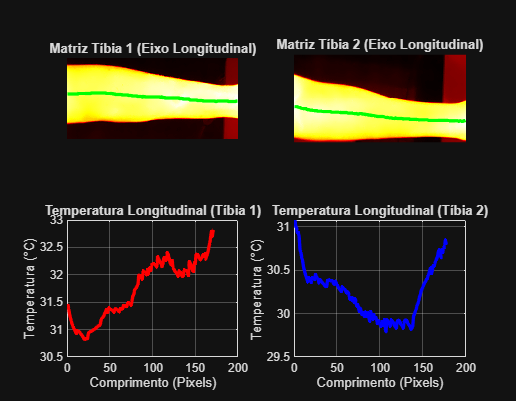

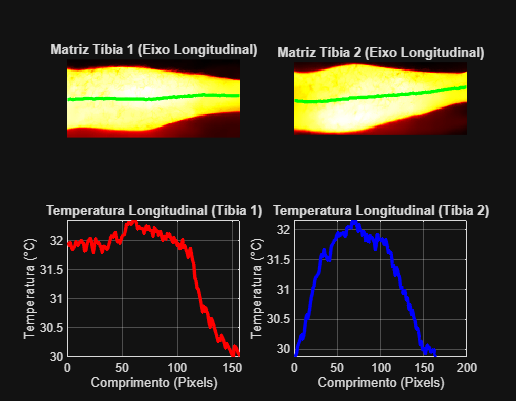

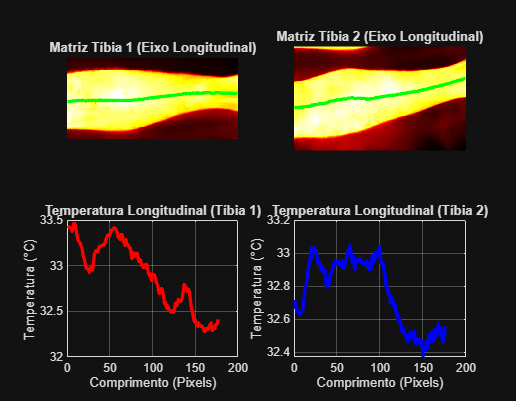

% =========================================================================
% PIPELINE DE SEGMENTAÇÃO TÉRMICA DA TÍBIA E PERFIL LONGITUDINAL
% =========================================================================

% 1. Definição do Caminho Principal (Ajustar para o teu diretório)
pasta_principal = "D:\Faculdade\Artigo cientifico\data-20261007T205415Z-1-001\data";

% 2. Criação do Datastore para mapear os ficheiros CSV
banco_de_dados = imageDatastore(pasta_principal, ...
    'IncludeSubfolders', true, ...           
    'LabelSource', 'foldernames', ...
    'FileExtensions', '.csv', ...       
    'ReadFcn', @readmatrix);            

% Garante que o ponteiro começa na primeira imagem
reset(banco_de_dados);

% 3. Laço Principal de Processamento
for i = 1:3
    % Lê a matriz de temperatura (CSV)
    img_termica = read(banco_de_dados);
    
    % --- PROCESSAMENTO GEOMÉTRICO ---
    % Isola as duas pernas baseando-se no contorno
    [perna1, perna2] = extrair_pernas_por_contorno(img_termica);
    
    % Aplica a heurística de corte para deixar apenas a região da tíbia
    tibia1 = extrair_tibia_heuristica(perna1);
    tibia2 = extrair_tibia_heuristica(perna2);
    
    % --- EXTRAÇÃO DE DADOS LONGITUDINAIS ---
    % Calcula o perfil de temperatura e as coordenadas da linha central
    [perfil1, eixo_y1] = extrair_perfil_e_linha(tibia1);
    [perfil2, eixo_y2] = extrair_perfil_e_linha(tibia2);
    
    % Eixo X para o desenho da linha (de 1 até a largura final da tíbia)
    eixo_x1 = 1:length(eixo_y1);
    eixo_x2 = 1:length(eixo_y2);
    
    % --- PLOTAGEM DO DASHBOARD ---
    figure('Name', sprintf('Análise Longitudinal com Linha Central - CSV %d', i), 'Position', [100, 100, 900, 700]);
    
    % Matriz Tíbia 1 COM A LINHA CENTRAL
    subplot(2, 2, 1);
    imagesc(tibia1); colormap('hot'); axis image off;
    hold on; 
    plot(eixo_x1, eixo_y1, 'g-', 'LineWidth', 2.5); 
    hold off;
    title('Matriz Tíbia 1 (Eixo Longitudinal)');
    
    % Gráfico Perfil Tíbia 1
    subplot(2, 2, 3);
    plot(eixo_x1, perfil1, 'r-', 'LineWidth', 2.5);
    grid on;
    title('Temperatura Longitudinal (Tíbia 1)');
    ylabel('Temperatura (°C)');
    xlabel('Comprimento (Pixels)');
    
    % Matriz Tíbia 2 COM A LINHA CENTRAL
    subplot(2, 2, 2);
    imagesc(tibia2); colormap('hot'); axis image off;
    hold on;
    plot(eixo_x2, eixo_y2, 'g-', 'LineWidth', 2.5);
    hold off;
    title('Matriz Tíbia 2 (Eixo Longitudinal)');
    
    % Gráfico Perfil Tíbia 2
    subplot(2, 2, 4);
    plot(eixo_x2, perfil2, 'b-', 'LineWidth', 2.5);
    grid on;
    title('Temperatura Longitudinal (Tíbia 2)');
    ylabel('Temperatura (°C)');
    xlabel('Comprimento (Pixels)');
end


% =========================================================================
% FUNÇÕES LOCAIS (Devem ficar obrigatoriamente no final do ficheiro)
% =========================================================================

function [img_perna_sup, img_perna_inf] = extrair_pernas_por_contorno(img_termica)
    % Normalização para cálculo de limiar
    img_norm = (img_termica - min(img_termica(:))) / (max(img_termica(:)) - min(img_termica(:)));
    mascara = imbinarize(img_norm, graythresh(img_norm));
    
    % Limpeza morfológica da máscara
    mascara_limpa = bwareaopen(mascara, 500);
    mascara_limpa = imfill(mascara_limpa, 'holes');
    
    % Extração de propriedades espaciais
    propriedades = regionprops(mascara_limpa, 'Area', 'BoundingBox');
    
    % Ordena os objetos por área para garantir que apanhamos as duas pernas
    areas = [propriedades.Area];
    [~, indices_ordenados] = sort(areas, 'descend'); 
    
    boxA = propriedades(indices_ordenados(1)).BoundingBox;
    boxB = propriedades(indices_ordenados(2)).BoundingBox;
    
    % Identifica qual perna está em cima (menor valor no eixo Y)
    if boxA(2) < boxB(2)
        box_superior = boxA;
        box_inferior = boxB;
    else
        box_superior = boxB;
        box_inferior = boxA;
    end
    
    % Recorta as matrizes térmicas exatas
    img_perna_sup = imcrop(img_termica, box_superior);
    img_perna_inf = imcrop(img_termica, box_inferior);
end

function img_tibia = extrair_tibia_heuristica(img_perna)
    largura_total = size(img_perna, 2);
    
    % Descarta os primeiros 20% (joelho) e apanha os próximos 55% (tíbia)
    coluna_inicio = max(1, round(largura_total * 0.20));
    coluna_fim = min(largura_total, coluna_inicio + round(largura_total * 0.55));
    
    % Fatiamento da matriz matricial direta
    img_tibia = img_perna(:, coluna_inicio:coluna_fim);
end

function [perfil_temp, linha_centro_y] = extrair_perfil_e_linha(img_tibia)
    % Identifica pele vs. fundo na sub-matriz
    img_norm = (img_tibia - min(img_tibia(:))) / (max(img_tibia(:)) - min(img_tibia(:)));
    limiar = graythresh(img_norm);
    mascara_perna = img_norm >= limiar;
    
    largura = size(img_tibia, 2);
    perfil_temp = zeros(1, largura);
    linha_centro_y = zeros(1, largura);
    
    % Varre cada coluna para achar o centro geométrico exato
    for x = 1:largura
        coluna_atual = mascara_perna(:, x);
        indices_pele = find(coluna_atual); 
        
        if ~isempty(indices_pele)
            % Coordenada Y da linha é o meio da pele naquela coluna
            linha_centro_y(x) = mean(indices_pele);
            % Temperatura média omitindo o fundo escuro
            perfil_temp(x) = mean(img_tibia(indices_pele, x));
        else
            linha_centro_y(x) = NaN;
            perfil_temp(x) = NaN;
        end
    end
end